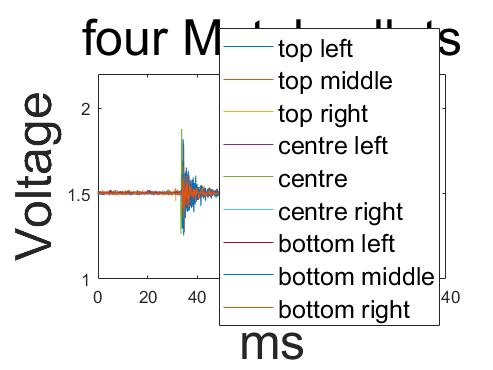

clear all
close all
clc

load("topmiddleMatal.mat")
initial = 1;
input_end = 5866; 
% 15283 for datasquare, 9232 for data4 12620 for data789 16310 for data666 
% 10870 for plastic, 5866 for matalTM
% Top left first right second 16270, 9808 for metal
% 4 corner 12526, 12301 for Metal
% all 17791, metal 16054
starting_position = 18000-input_end+1;
not_9 = 0;

x_axis = 0:1/15:400/3-1/15;

while not_9 == 0
    if mod(starting_position,9) == 0
        not_9 = 1;
    else
        starting_position = starting_position + 1;
    end
end
k = 1;
temp = 1;
for i = 1:9
    for j = starting_position+1:9:18000
        channel(i,k) = topmiddleMatal(j);
        k = k + 1;
    end
    k = k - 1;
    for j = temp:9:starting_position+1
        channel(i,k) = topmiddleMatal(j);
        k = k + 1;
    end
    k = 1;
    temp = temp + 1;
    starting_position = starting_position + 1;
    channel(i,:) = channel(i,:)./4096*3;
end

channel(1,:) = -(channel(1,:)-1.5)*0.38+1.5;
lowlimit = 1;
highlimit = 2.2;
%%% all in one %%%
plot(x_axis,channel)
xlabel('ms',FontSize=30)
ylabel('Voltage',FontSize=30)
title('four Metal pellets',FontSize=30)
legend('top left','top middle','top right','centre left','centre','centre right', ...
    'bottom left','bottom middle','bottom right',Location='best',FontSize=15)
ylim([lowlimit highlimit])
hold off

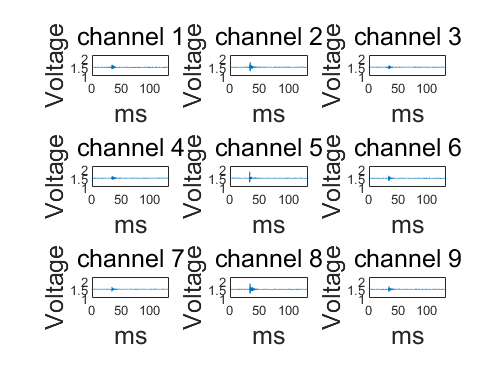


%%% 3x3 diagram %%%
subplot(3,3,1)
plot(x_axis,channel(1,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 1',FontSize=15)
ylim([lowlimit highlimit])

subplot(3,3,2)
plot(x_axis,channel(2,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 2',FontSize=15)
ylim([lowlimit highlimit])

subplot(3,3,3)
plot(x_axis,channel(3,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 3',FontSize=15)
ylim([lowlimit highlimit])

subplot(3,3,4)
plot(x_axis,channel(4,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 4',FontSize=15)
ylim([lowlimit highlimit])

subplot(3,3,5)
plot(x_axis,channel(5,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 5',FontSize=15)
ylim([lowlimit highlimit])

subplot(3,3,6)
plot(x_axis,channel(6,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 6',FontSize=15)
ylim([lowlimit highlimit])

subplot(3,3,7)
plot(x_axis,channel(7,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 7',FontSize=15)
ylim([lowlimit highlimit])

subplot(3,3,8)
plot(x_axis,channel(8,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 8',FontSize=15)
ylim([lowlimit highlimit])

subplot(3,3,9)
plot(x_axis,channel(9,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 9',FontSize=15)
ylim([lowlimit highlimit])

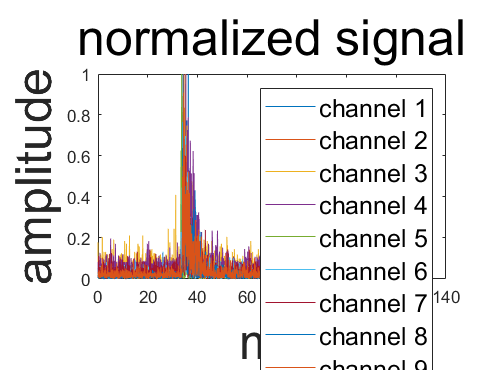


% centre the signal at 0
for i = 1:9
    tempmax = max(abs(channel(i,:)-1.5));
    normalizedchannel(i,:) = abs(channel(i,:)-1.5)./(tempmax);
%     normalizedchannel(i,:) = abs((channel(i,:) - mean(channel(i,:))) / std(channel(i,:)));
end
figure, plot(x_axis,normalizedchannel)
xlabel('ms',FontSize=30)
ylabel('amplitude',FontSize=30)
title('normalized signal',FontSize=30)
legend('channel 1','channel 2','channel 3', 'channel 4', 'channel 5', 'channel 6', ...
    'channel 7', 'channel 8', 'channel 9',FontSize=15)

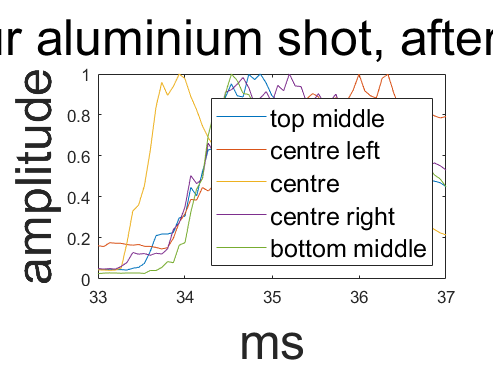

% xlim([33.33 51.33])

%%%%%%%%%%%%%%% Kalman filter %%%%%%%%%%%%%%%
% Define the system parameters
A = 1;          % State transition matrix
C = 1;          % Measurement matrix
Q = 0.01;       % Process noise covariance
R = 1;          % Measurement noise covariance

% Initialize the Kalman filter
channelhat = zeros(size(normalizedchannel));         % Initialize the estimated signal
sizeofchannel = size(normalizedchannel);
P = zeros(sizeofchannel);            % Initialize the error covariance
channelhat(:,1) = normalizedchannel(:,1);                % Set the initial estimate to the first measurement
P(:,1) = R;                      % Set the initial error covariance to the measurement noise covariance

% Apply the Kalman filter to the signal
for k = 2:length(normalizedchannel)
    % Predict the state estimate and error covariance
    xhatminus = A * channelhat(:,k-1);
    Pminus = A * P(k-1) * A' + Q;

    % Update the state estimate and error covariance
    K = Pminus * C' / (C * Pminus * C' + R);
    channelhat(:,k) = xhatminus + K * (normalizedchannel(:,k) - C * xhatminus);
    P(k) = (1 - K * C) * Pminus;
end
%%% normalization %%%
for i = 1:9
    tempmax = max(abs(channelhat(i,:)));
    channelhat(i,:) = abs(channelhat(i,:))./(tempmax);
end
% %%% Threshold %%%
% for i = 1:9
%     for j = 1:2000
%         if channelhat(i,j) <= 0.99999
%             channelhat(i,j) = 0.01;
%         end
%     end
% end

figure, plot(x_axis,channelhat(2,:))
hold on
plot(x_axis,channelhat(4,:))
plot(x_axis,channelhat(5,:))
plot(x_axis,channelhat(6,:))
plot(x_axis,channelhat(8,:))
% figure, plot(x_axis,channelhat)
xlabel('ms',FontSize=30)
ylabel('amplitude',FontSize=30)
title('four aluminium shot, after filter',FontSize=30)
% legend('top left','top middle','top right','centre left','centre','centre right', ...
%     'bottom left','bottom middle','bottom right',Location='southeast',FontSize=15)
legend('top middle','centre left','centre','centre right', ...
    'bottom middle',Location='southeast',FontSize=15)
xlim([33 37])

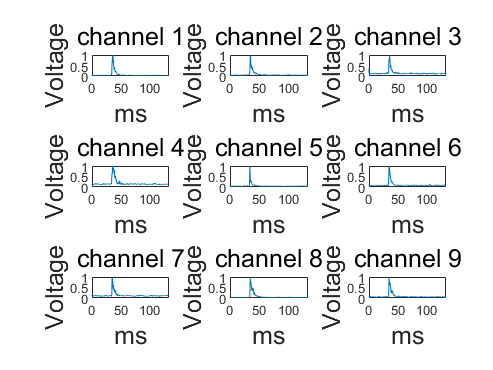


%%%%% after filter %%%%%
subplot(3,3,1)
plot(x_axis,channelhat(1,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 1',FontSize=15)
ylim([0 1])

subplot(3,3,2)
plot(x_axis,channelhat(2,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 2',FontSize=15)
ylim([0 1])

subplot(3,3,3)
plot(x_axis,channelhat(3,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 3',FontSize=15)
ylim([0 1])

subplot(3,3,4)
plot(x_axis,channelhat(4,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 4',FontSize=15)
ylim([0 1])

subplot(3,3,5)
plot(x_axis,channelhat(5,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 5',FontSize=15)
ylim([0 1])

subplot(3,3,6)
plot(x_axis,channelhat(6,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 6',FontSize=15)
ylim([0 1])

subplot(3,3,7)
plot(x_axis,channelhat(7,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 7',FontSize=15)
ylim([0 1])

subplot(3,3,8)
plot(x_axis,channelhat(8,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 8',FontSize=15)
ylim([0 1])

subplot(3,3,9)
plot(x_axis,channelhat(9,:))
xlabel('ms',FontSize=15)
ylabel('Voltage',FontSize=15)
title('channel 9',FontSize=15)
ylim([0 1])